# **Script illustrating the relationship between human and treeshrew cone excitation levels**

*This script illustrates how and why cone excitation levels differ between human and treeshrew models*

*See also: ls_optics_TreeShrew_VS_Human.mlx*

*Copyright: Nicolas P. Cottaris,  ISETBio Team, 2018*

# **Step 1a.** Generate default human and treeshrew optics with 2mm pupil

% Default treeshrew optics, here with 2.0 mm pupil
pupilDiameterMM = 2.0

pupilDiameterMM = 2

tOI = oiTreeShrewCreate('pupilDiameterMM', pupilDiameterMM);
% Default human optics, here with 2.0 mm pupil
hOI = oiCreate('wvf human', pupilDiameterMM);

# **Step 1b.** Generate human and treeshrew L-cone only mosaics

#### Generate human and treeshrew L-cone only mosaics

% Specify an L-only mosaic (densities of other cones is 0)
spatialLMSdensities = [0 1 0 0];
% 0.1 x 0.1 deg mosaic for the human
fovDegs = 0.1*[1 1];
% human mosaic
hMosaic = coneMosaicHex(7, ...
    'spatialDensity', spatialLMSdensities, ...
    'integrationTime', 5/1000, ...
    'fovDegs', fovDegs);


Resampling grid. Please wait ... Done !
Will not change the S-cone density.
Scones before making an S-cone free central patch: 0
Scones after making an S-cone free central patch: 0 (added Lcones:0, added Mcones:0)


% 0.4 x 0.4 deg mosaic for the treeshrew
fovDegs = 0.4*[1 1];
tMosaic = coneMosaicTreeShrewCreate(tOI.optics.micronsPerDegree, ...
    'spatialDensity', spatialLMSdensities, ...
    'integrationTime', 5/1000, ...
    'fovDegs', fovDegs);


Resampling grid. Please wait ... Done !
Will not change the S-cone density.
Scones before making an S-cone free central patch: 0
Scones after making an S-cone free central patch: 0 (added Lcones:0, added Mcones:0)


#### Visualize the mosaics

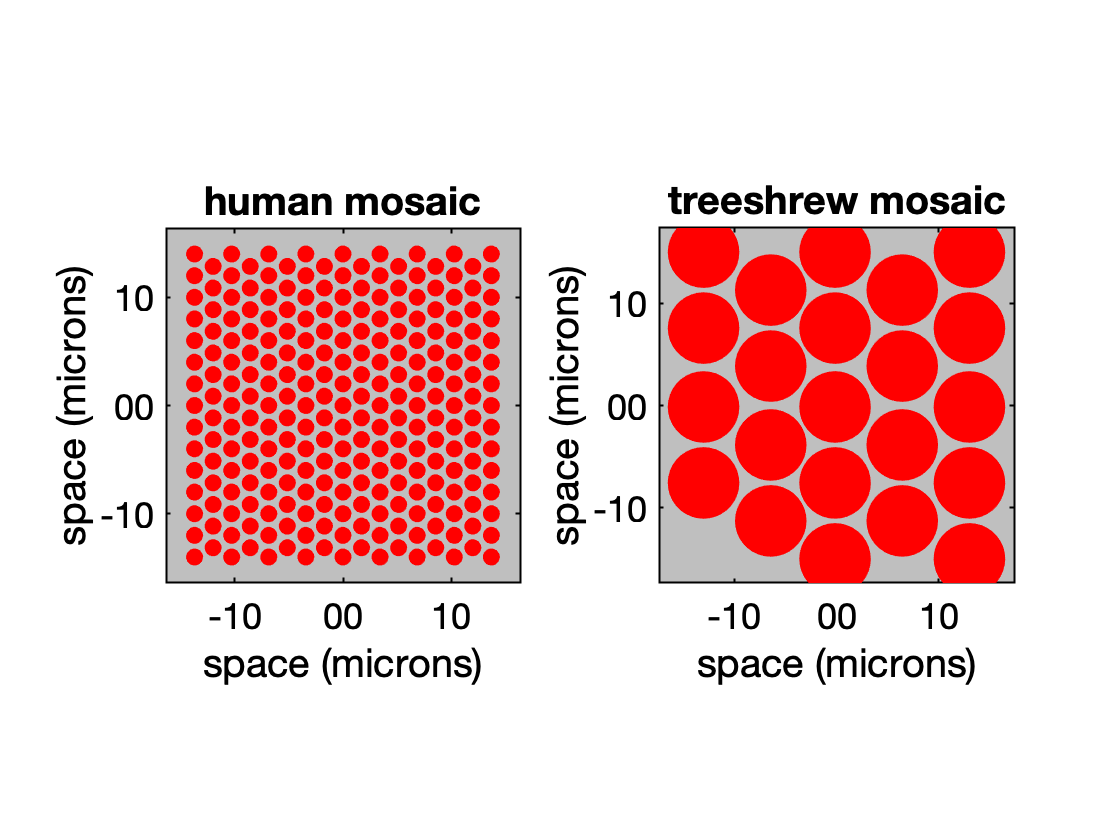

% Plot mosaics
figure(); clf;
subplot(1,2,1);
hMosaic.visualizeGrid('axesHandle', gca, 'ticksInMicrons', true);
title('human mosaic')

subplot(1,2,2);
tMosaic.visualizeGrid('axesHandle', gca, 'ticksInMicrons', true);
title('treeshrew mosaic')

# **Step 2.** Create a scene that emits equal photon rates at all wavelengths and compute the optical image for the human and treeshrew optics

% Create the equal photon rate test scene
testScene = sceneCreate('uniformEqualPhoton');
% Compute the retinal images
tOI = oiCompute(tOI, testScene);
hOI = oiCompute(hOI, testScene);

% Retrieve the retinal irradiances
meanIlluminanceTreeShrewRetina = oiGet(tOI, 'mean illuminance')

meanIlluminanceTreeShrewRetina = 14.3413

meanIlluminanceHumanRetina = oiGet(hOI, 'mean illuminance')

meanIlluminanceHumanRetina = 0.8480


% Compute ratio of mean illuminances
meanIlluminanceRatio = meanIlluminanceTreeShrewRetina/meanIlluminanceHumanRetina

meanIlluminanceRatio = 16.9127

Note that the mean retinal illuminance in the treeshrew retina is around 17 times that of the human retina. This is mostly because the focal length in the treeshrew is 4.35 mm, vs. 17 mm in the human, and illuminance drops with the square of distance. Indeed (17/4.35)^2 = 15.3

# **Step 3. **Compute treeshrew and human cone mosaic responses to the test scene

% Compute the mosaic responses
nTrialsNum = 3;
emPath = zeros(nTrialsNum, 1, 2);

% Compute *human* mosaic excitation responses to the *human* retinal image
hMosaicExcitation = hMosaic.compute(hOI, 'emPath', emPath);
% Compute *treeshrew* mosaic excitation responses to treeshrew optical image
tMosaicExcitation = tMosaic.compute(tOI, 'emPath', emPath);

% Find mean excitations
coneType = 2;
hMosaicExcitationMean = ...
    meanResponseToOpticalImage(hMosaic, hMosaicExcitation, coneType)

hMosaicExcitationMean = 17.2767

tMosaicExcitationMean = ...
    meanResponseToOpticalImage(tMosaic, tMosaicExcitation, coneType)

tMosaicExcitationMean = 658.4242


meanExcitationRatio = tMosaicExcitationMean / hMosaicExcitationMean

meanExcitationRatio = 38.1106

Here we see that the treeshrew mosaic excitation is 38-times higher than the human mosaic exciation. One factor contributing to this is the difference in retinal illuminances. But only account for around a 17-x factor. The remaining must be due to cone sensitivities. We examine this next.

# **Step 4. Examine how different components of cone sensitivity contrinute to differences in cone isomerizations between human and treeshew models**

#### 4.1 Absorbance spectrum (spectral absorbance)

The absorbance, A, of a material, is defined as  the logarithm of the ratio of the radiance incident to the material to the radiance transmitted by the material: $A={\mathrm{log}}_{10} \left(\frac{\Phi_i }{\Phi_t }\right)$ . Spectral absorbance is the absorbance as a function of wavelength. Below the plot the normalized spectral absorbance of the human and the tree shrew pigments.

% Extract the pigment structure from the cone mosaic.
w = hMosaic.wave;
hPigment = hMosaic.pigment

hPigment =   photoPigment with properties:

        opticalDensity: [3×1 double]
        peakEfficiency: [3×1 double]
                 width: 1.7725e-06
                height: 1.7725e-06
               pdWidth: 1.4000e-06
              pdHeight: 1.4000e-06
                  wave: [31×1 double]
            absorbance: [31×3 double]
           absorptance: [31×3 double]
    quantaFundamentals: [31×3 double]
    energyFundamentals: [31×3 double]
                  area: 3.1416e-12
                pdArea: 1.9600e-12
              gapWidth: 3.7245e-07
             gapHeight: 3.7245e-07


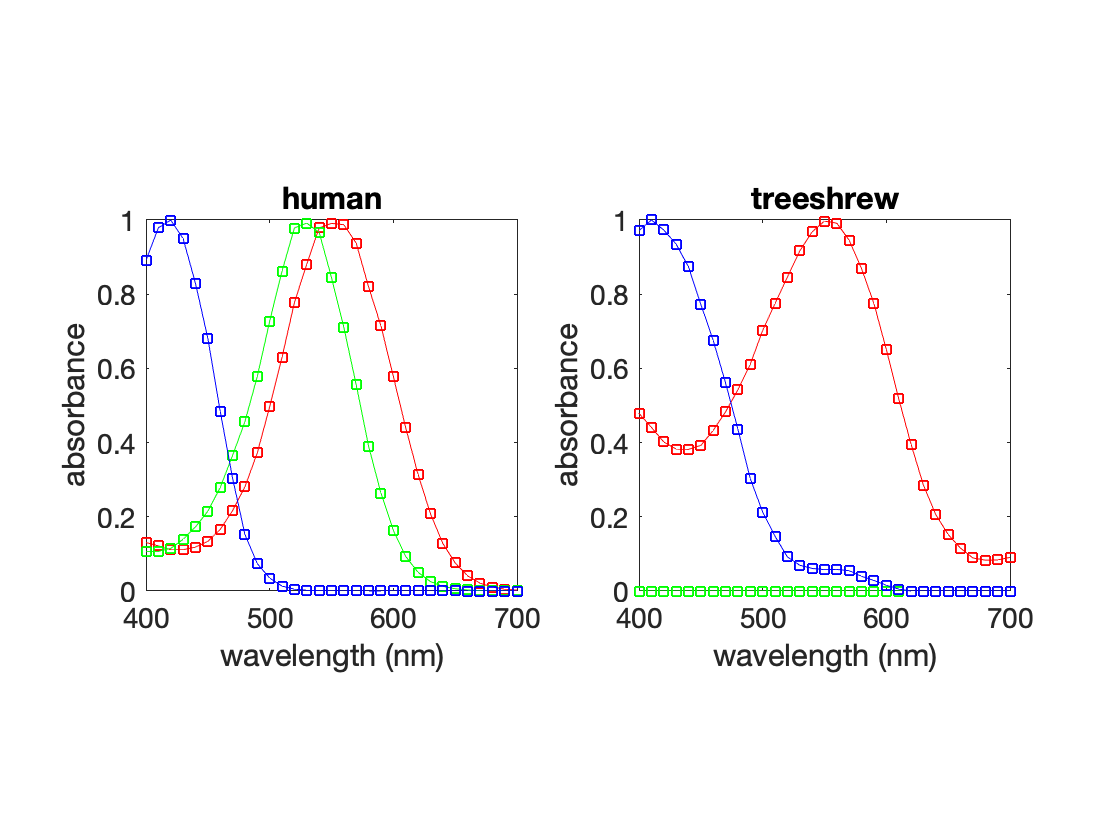


wT = tMosaic.wave;
tPigment = tMosaic.pigment;

% Retrieve the normalized spectal absorbance. 
% Note that these are normalized to peak value of 1.
humanAbsorbance = hPigment.absorbance;
treeShrewAbsorbance = tPigment.absorbance;

% Plot them
figure();
subplot(1,2,1)
plotActionSpectra(w, humanAbsorbance, 'absorbance', 'human')
subplot(1,2,2)
plotActionSpectra(wT, treeShrewAbsorbance, 'absorbance', 'treeshrew')

To get the actual absorbance, we have to multiply the normalize absorbance by the axial optical density of the pigments. We do this below.

#### 4.2 Axial absorbance spectrum

% Compute the axial absorbance, absorbance * axial optical density
axialDensities = hPigment.opticalDensity;

axialDensities =     0.5000
    0.5000
    0.4000


humanAxialAbsorbance = humanAbsorbance * diag(axialDensities);
axialDensities = tPigment.opticalDensity;

axialDensities =     0.0370
         0
    0.0389


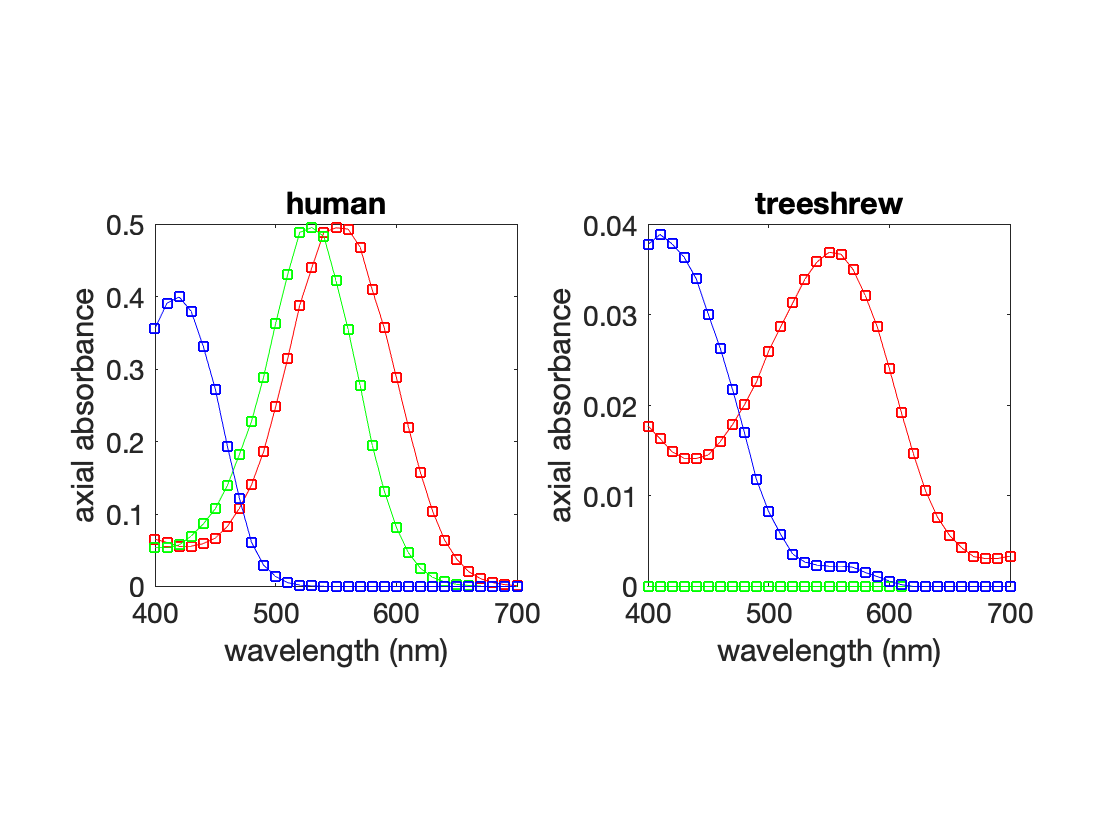

treeShrewAxialAbsorbance = treeShrewAbsorbance * diag(axialDensities);

% Plot them
figure()
subplot(1,2,1)
plotActionSpectra(w, humanAxialAbsorbance, 'axial absorbance', 'human')
subplot(1,2,2)
plotActionSpectra(w, treeShrewAxialAbsorbance, 'axial absorbance', 'treeshrew')

Note that the axial absorbance of treeshrew cone photopigment is an order of magniture lower than that of human cone photopigments. This means that the treeshrew cone photopigments absorb less photons than human photopigments. Lets compute the percentange of photons absorbed. Absorptance is the ratio of the absorbed photons to the incident photons. Since $\Phi_i =\Phi_t +\Phi_a$ where $\Phi_a$denotes the absorbed photons, 

It can be proven that $\frac{\Phi_a }{\Phi_i }=1-{10}^{\left(-A\right)}$, where $A$ is the axial absorbance. 

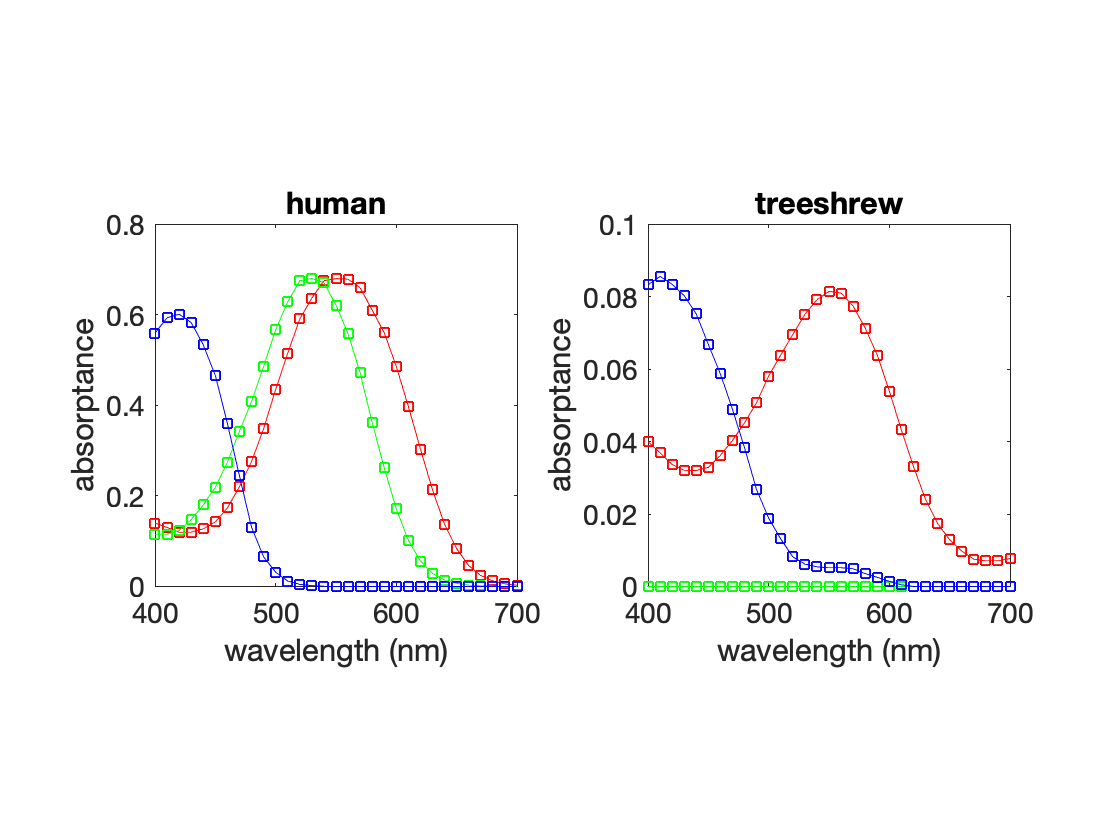

% Compute human and tree shrew absorptances
humanAbsorptance = 1 - 10 .^ (-humanAxialAbsorbance);
treeShrewAbsorptance = 1 - 10 .^ (-treeShrewAxialAbsorbance);
% Plot them
figure()
subplot(1,2,1)
plotActionSpectra(w, humanAbsorptance, 'absorptance', 'human')
subplot(1,2,2)
plotActionSpectra(w, treeShrewAbsorptance, 'absorptance', 'treeshrew')

We see that the absorbed photons are about 10 times lower in the treeshrew than in the human photopigment.This is in the opposite direction of explaining why  cone isomerization levels in the treeshrew are higher than those of humans. There must be a different region for the higher efficiency of treeshrew cones. We examine this below.

#### 4.3 Cone efficiency

We begin by computed the quantal cone efficiency, which the product of the peak efficiency and absorptance.

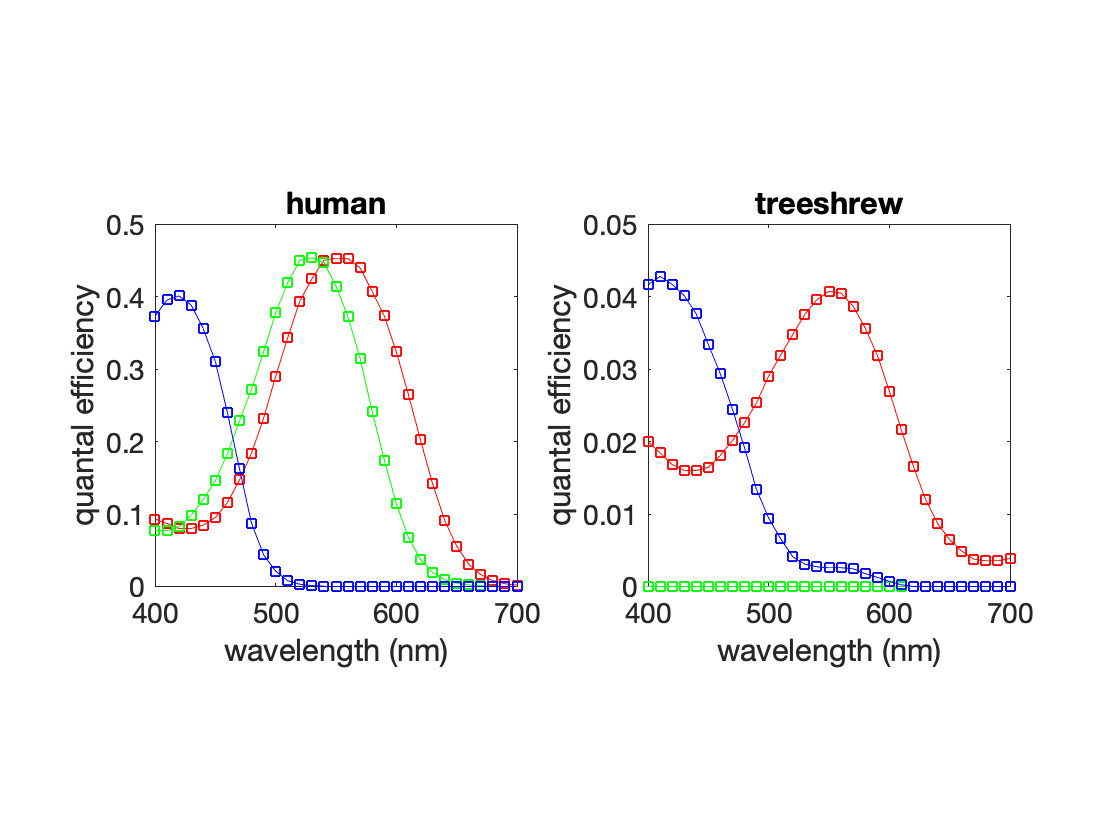

% Compute quantal cone efficiencies (not accounting for macular/lens pigments)
peakEfficiencies = hPigment.peakEfficiency;
humanQuantalEfficiency = humanAbsorptance * diag(peakEfficiencies);
peakEfficiencies = tPigment.peakEfficiency;
treeShrewQuantalEfficiency = treeShrewAbsorptance * diag(peakEfficiencies);
% Plot them
figure()
subplot(1,2,1)
plotActionSpectra(w, humanQuantalEfficiency, 'quantal efficiency', 'human')
subplot(1,2,2)
plotActionSpectra(w, treeShrewQuantalEfficiency, 'quantal efficiency', 'treeshrew')

Next, we computed the integrated (over the cone aperture) quantal efficiency. Note that cones absorb photons collected over their inner segment diameter, and it is the integrated quantal efficiency what drives the cone excitation level

% Compute integrated (over cone aperture) quantal efficiency 
humanInnerSegmentArea = hPigment.pdArea*1e12

humanInnerSegmentArea = 1.9600

humanIntegratedQuantalEfficiency = humanQuantalEfficiency * humanInnerSegmentArea;
treeShrewInnerSegmentArea = tPigment.pdArea*1e12

treeShrewInnerSegmentArea = 38.4845

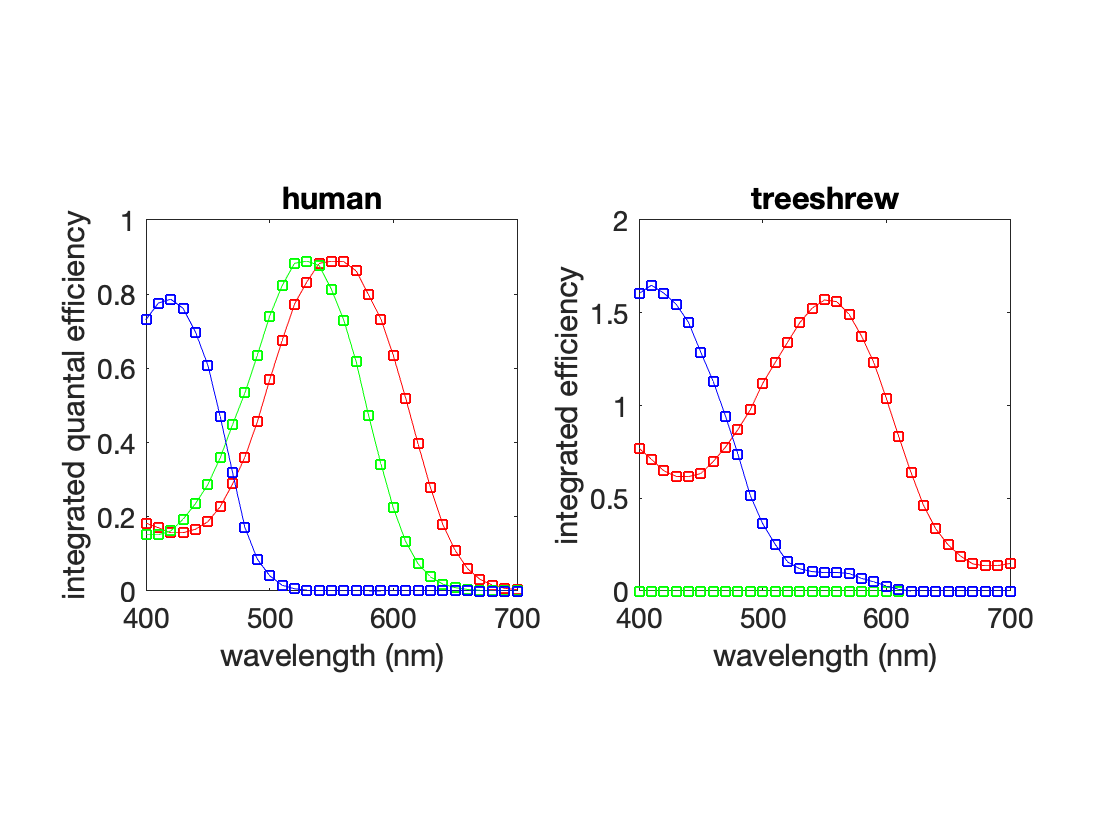

treeShrewIntegratedQuantalEfficiency = treeShrewQuantalEfficiency * treeShrewInnerSegmentArea;
% Plot them
figure()
subplot(1,2,1)
plotActionSpectra(w, humanIntegratedQuantalEfficiency, 'integrated quantal efficiency', 'human')
subplot(1,2,2)
plotActionSpectra(w, treeShrewIntegratedQuantalEfficiency, 'integrated efficiency', 'treeshrew')

We see now that despite the lower absorbance of treeshrew photopigment, their actual cone efficiency is  higher than that of humans. This is because of their large inner segment diameters. 

Ane finally, if we integrated over wavelength (below), we see that the treeshrew cones are about 2-2.5 times more sensitive then human cones for an equal-photon stimulus. This explains why 

% Integrate quantal efficiency over wavelength
humanSpectrallyIntegratedQuantalEfficiencies = sum(humanIntegratedQuantalEfficiency,1)

humanSpectrallyIntegratedQuantalEfficiencies =    12.4923   10.8496    5.4770


treeshrewSpectrallyIntegratedQuantalEfficiencies  = sum(treeShrewIntegratedQuantalEfficiency,1)

treeshrewSpectrallyIntegratedQuantalEfficiencies =    25.5108         0   13.9079


coneEfficiencyRatios = treeshrewSpectrallyIntegratedQuantalEfficiencies./humanSpectrallyIntegratedQuantalEfficiencies

coneEfficiencyRatios =     2.0421         0    2.5393


Indeed the product of the meanIlluminanRatio with the coneEfficiencyRatios is close the the meanExciationRatio obtained wo the equal-photon scene as seen below

meanIlluminanceRatio * coneEfficiencyRatios(1)

ans = 34.5377

meanExcitationRatio

meanExcitationRatio = 38.1106

Any remaining differences are due to differences in short-wavelength absorption by the lens, and due to the fact that in the human retina there is additional short-wavelenth absorption by the macular pigment, whereas in the treeshrew model there is no macular pigment.

function plotActionSpectra(w, a, aName, tName)
    plot(w, a(:,1), 'rs-'); hold on;
    plot(w, a(:,2), 'gs-');
    plot(w, a(:,3), 'bs-');
    axis 'square'
    xlabel('wavelength (nm)')
    ylabel(aName)
    title(tName)
    set(gca, 'FontSize', 14)
end



function meanResponse = meanResponseToOpticalImage(coneMosaic, coneMosaicResponse, targetConeType)
    nTrialsNum = size(coneMosaicResponse,1);
    coneMosaicResponse  = reshape(coneMosaicResponse, [nTrialsNum numel(coneMosaic.pattern)]);
    idx = find(coneMosaic.pattern == targetConeType);
    meanResponse = mean(mean(coneMosaicResponse(:,idx)));
end
